clear
close all
clc

# **TIME SERIES ANALYSIS ON S&P 500 DATASET**

## **Information on the Dataset**

**Title** : S&P 500 stock data

**Source** : Kaggle datasets ([https://www.kaggle.com/camnugent/sandp500](https://www.kaggle.com/camnugent/sandp500))

**Relevant information **:

    One of the most useful real world application of Machine Learning and Data Science in general is the analysis and forecasting of stock market data. The S&P 500 is a stock market index that tracks the stocks of 500 large-cap U.S. companies. This dataset contains historical data of the S&P 500 index (2013 - 2018 [5 years]). Historical data might offer insights on stock markets and might allow us to predict future trends.

**Attribute Information** :

    Each file in the dataset has data in the following format,

- **Date** - in format: yy-mm-dd

- **Open** - Price of the stock at market open (this is NYSE data so all in USD)

- **High** - Highest price reached in the day

- **Low** - Lowest price reached in the data

- **Close **- Price of stock at market close

- **Volume** - Number of shares traded

- **Name** - The stock's ticker name

**The goal of this project is to analyze the NFLX dataset from S&P 500 dataset by fitting an ARIMA + GARCH model and forecast the stock price volatility.**

# **Generalized AutoRegressive Conditional Heteroskedastcity model**** (GARCH)**

        GARCH is a process describes an approach to estimate volatility in financial markets. The GARCH process is often preferred by financial modeling professionals because it provides a more real-world context than other forms when trying to predict the prices and rates of financial instruments.

        Garch tries to predict the volatility in the data. Therefore we need to fit an ARIMA model to the data before we fit the garch model.

## **Loading and cleaning the data**

data = readtable("NFLX_data.csv");     %Netflix stock data for ARIMA + GARCH model
T = table2timetable(data);

%Dropping Name attribute
T = removevars(T, 'Name');

fprintf("Maximum difference between two dates in hours is: %s", max(diff(T.date)))

Maximum difference between two dates in hours is: 96:00:00

As time distribution is not uniform, make difference betweeen successive days to 96 hours (4 days)

T = retime(T, 'regular', 'mean', 'TimeStep', '96:00:00');

## **Exploratory Data Analysis**

#### ***Displaying the table***

head(T)

ans = 8×5 timetable
       date        open      high      low      close       volume  
    __________    ______    ______    ______    ______    __________

    2013-02-08    25.766    26.144    25.344    25.633    2.7486e+07
    2013-02-12    26.336    26.779     25.94    26.469    3.3452e+07
    2013-02-16    27.286    28.167    27.164    28.064    3.4126e+07
    2013-02-20    27.014    27.315    26.068    26.387    3.6885e+07
    2013-02-24     25.96    26.587    25.315    26.082    3.6206e+07
    2013-02-28    26.494    27.319    26.409    26.961     2.787e+07
    2013-03-04    26.268     26.53    25.374     25.98    3.1555e+07
    2013-03-08    

#### *Plotting all attributes against time*

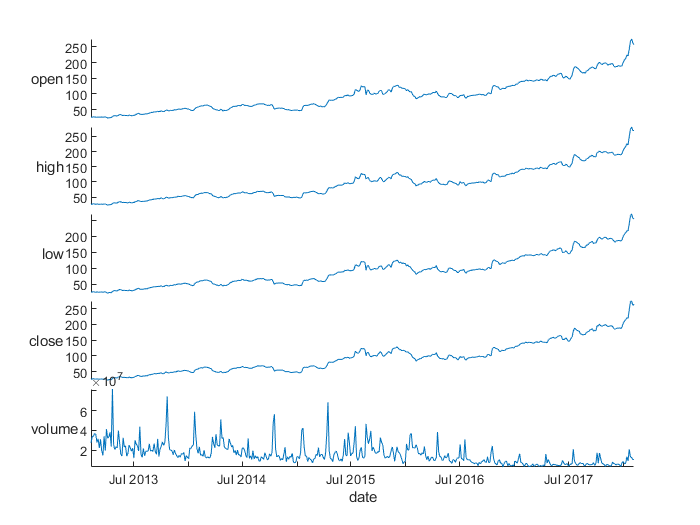

stackedplot(T, {'open', 'high', 'low', 'close', 'volume'});

Let's analyze closing market stock prices a bit closer

#### *Plotting price of stock at market close against time *

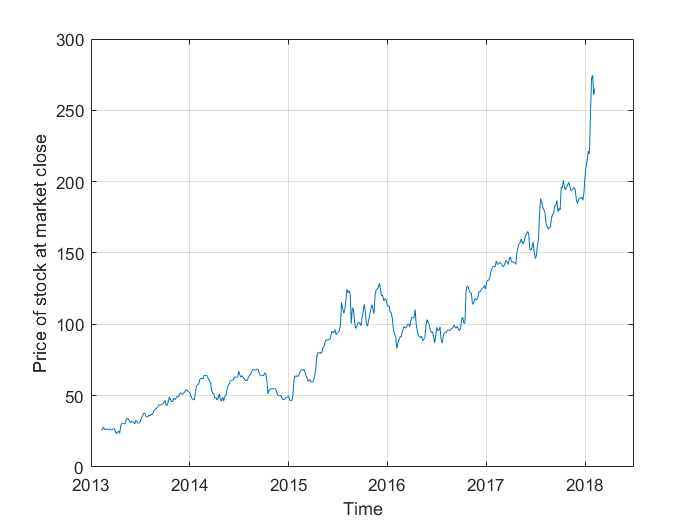

plot(T.date, T.close);
xlabel("Time")
ylabel("Price of stock at market close")
grid on

From the above plot we can see that there is an increasing trend in the data.

#### *Plotting first order difference of stock at market close versus time*

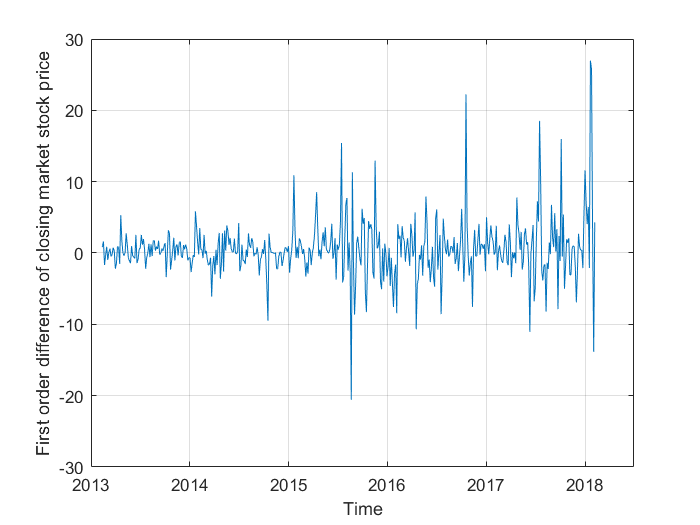

plot(T.date(2:end),diff(T.close));
grid on
ylabel("First order difference of closing market stock price")
xlabel("Time")

        From the above plots we can see that Market close stock prices is not a stationary while first order difference is stationary. This can be confirmed by Augmented - Dickey Fuller Test which tests for unit root. If ADF returns 1 then the series is stationary

adftest(T.close)

ans = logical
   0


adftest(diff(T.close))

ans = logical
   1


#### ***Autocorrelation and Partial autocorrelation***

Autocorrelation for first order difference of closing market stock price

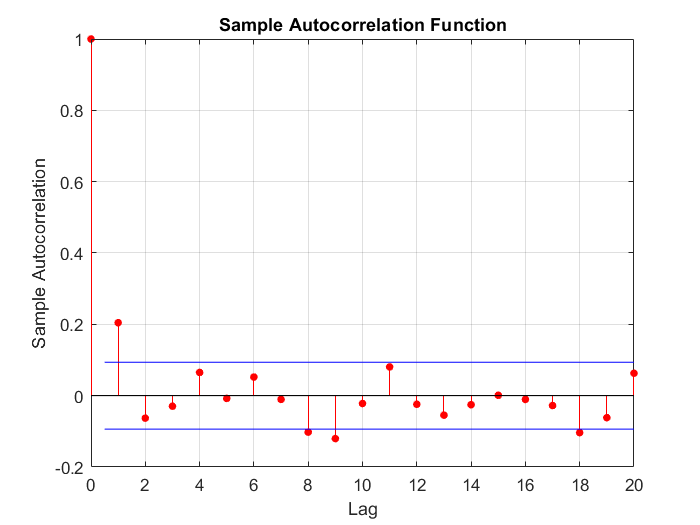

autocorr(diff(T.close))

Partial autocorrelation for first order difference of closing market stock price

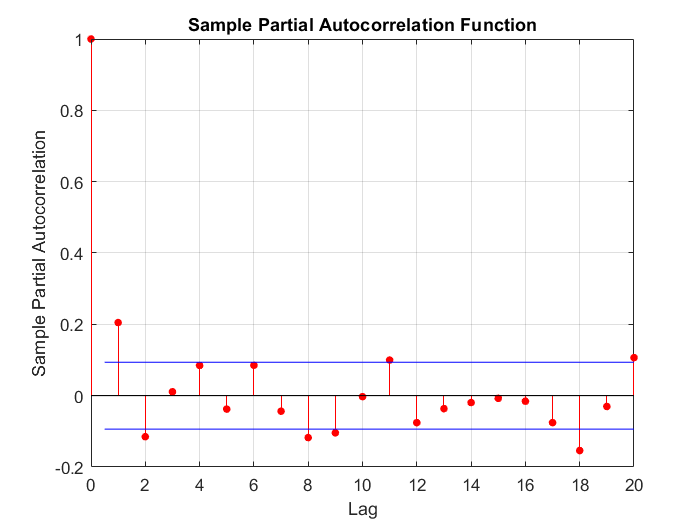

parcorr(diff(T.close))

From the above plots we can see that significant autocorrelation and partial autocorrelation occurs at lag 1

**From the above analysis we can see that**

- **The market close stock prices is not stationary with respect to time but its first order difference is stationary. Therefore the integration factor of the ARIMA model should be 1 as stationarity is a necsessary condition for ARIMA modelling.**

- **The autocorrelation is somewhat significant for lag 1. Therefore MA parameter should be 1.**

- **The partial autocorrelation is somewhat significant for lag 1. Therefore AR parameter should be 1.**

**Therefore ARIMA(1,1,1) model should be a good fit for this data.**

## **Fitting the model, evaluation and forecasting**** ARIMA(1,1,1)**

#### ***Dividing into training(70%) and test(30%) sets***

b = round(0.7*size(T, 1));
Train = timetable(T.date(1:b), T.close(1:b), 'VariableNames', {'close'});
Test = timetable(T.date(b+1:end), T.close(b+1:end), 'VariableNames', {'close'});

#### *Fitting the ARIMA model*

The model is fit using MATLAB's Econometrics Toolbox

Mdl = arima(1,1,1);
Estmdl = estimate(Mdl, Train.close, 'Display', 'off');
summarize(Estmdl)

 
   ARIMA(1,1,1) Model (Gaussian Distribution)
 
    Effective Sample Size: 320
    Number of Estimated Parameters: 4
    LogLikelihood: -824.143
    AIC: 1656.29
    BIC: 1671.36
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.28762       0.28894        0.99546          0.31951
    AR{1}       -0.40141       0.18174        -2.2087         0.027195
    MA{1}        0.55844       0.17713         3.1527        0.0016174
    Variance      10.105       0.37028         27.289      5.6658e-164

 
 


#### *Residual Analysis*

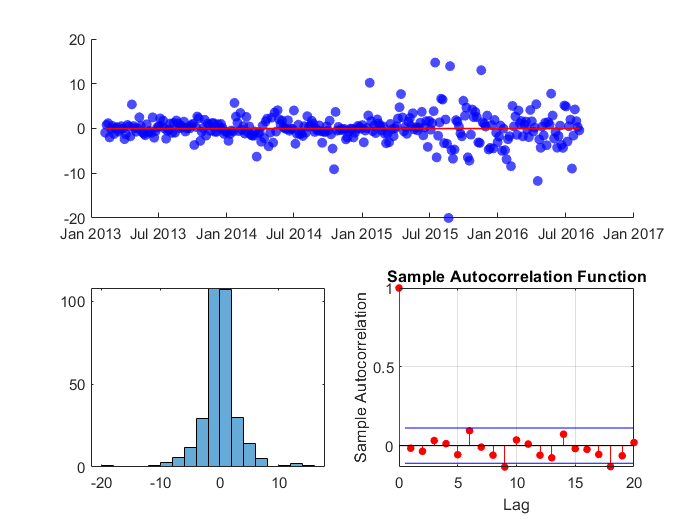

subplot(2,2, [1 2])
res = infer(Estmdl, Train.close);
scatter(Train.Time, res, 'filled', 'b', 'MarkerFaceAlpha', 0.7)
hold on
plot(Train.Time, 0*Train.close, 'red', 'LineWidth', 1)
hold off
subplot(2,2,3)
histogram(res)
subplot(2,2,4)
autocorr(res)

**From the above 3 plots we can see that**

- **Residuals have mean approx. 0.**

- **The residuals are normally distributed**

- **The residuals have no correlation among each other**

**This justifies our ARIMA model.**

## Exploratory Data Analysis for GARCH

#### ***Plotting residual and squared residual***

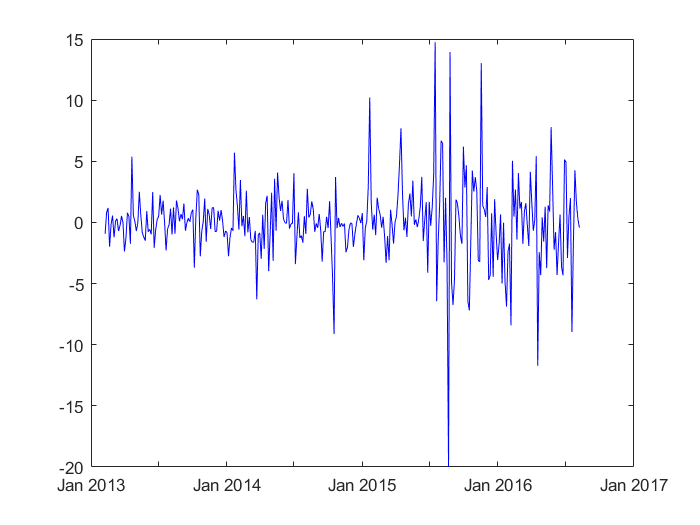

figure
sqres = res.*res;
plot(Train.Time, res, 'b')

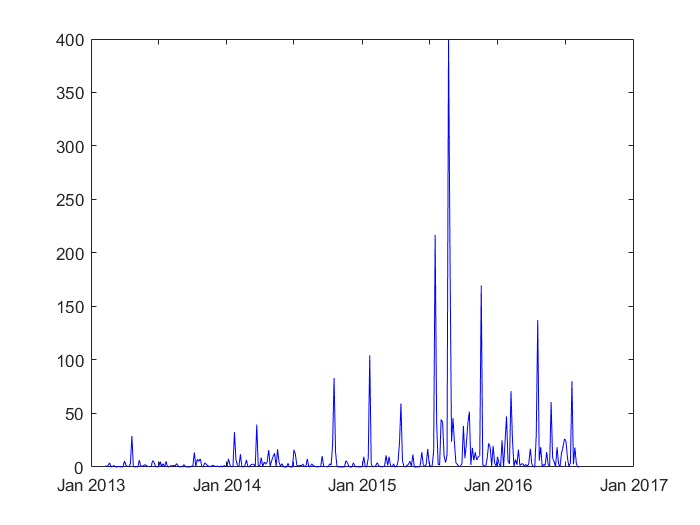

plot(Train.Time, sqres, 'b')

From the above plot we can see that there exists clustering of squared residuals.

#### *Autocorrelation and partial autocorrelation of squared residuals*

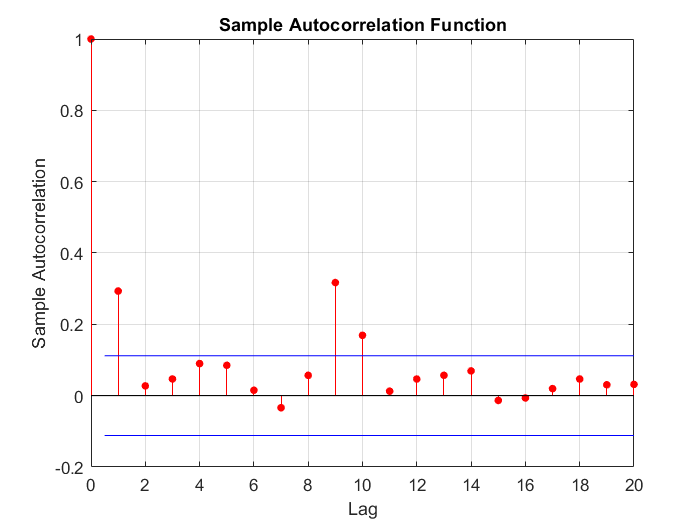

autocorr(sqres)

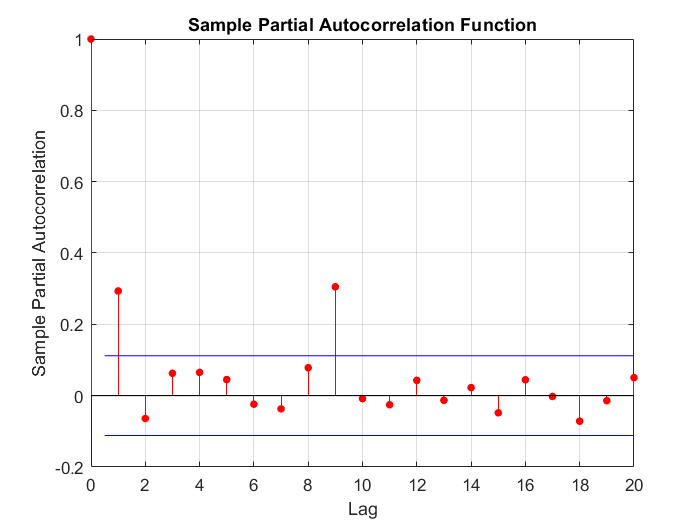

parcorr(sqres)

There seems to be significant AC and PAC at lag 9. Thus GARCH model can be applied for residuals.

## Estimating model order

All possible Garch models are applied from GARCH(1,1) to GARCH(9,9) to see the model that gives the best fit. The best fit is the model that gives the minimum Akaike Information Criterion (AIC).

S = zeros(81,3);
for i = 1:9
    for j = 1:9
        gMdl = garch(i,j);
        gEstmdl = estimate(gMdl, res, 'Display', 'off');
        s = summarize(gEstmdl);
        S(9*(i-1)+j,:) = [i, j, s.AIC];
    end
end

Tab = table(S(:,1), S(:,2), S(:,3), 'VariableNames', {'P','Q','AIC'})

Tab = 81×3 table
    P    Q     AIC  
    _    _    ______

    1    1    1565.6
    1    2    1567.6
    1    3    1565.5
    1    4    1550.3
    1    5    1552.3
    1    6    1554.3
    1    7    1555.8
    1    8    1550.5
    1    9    1535.8
    2    1      1558
    2    2      1560
    2    3      1562
    2    4    1552.3
    2    5    1554.3
    2    6    1556.3
    2    7    1557.5


Tab((Tab.AIC == min(Tab.AIC)), :) %Row with minimum AIC

ans = 1×3 table
    P    Q     AIC  
    _    _    ______

    8    1    1531.9


From the above table we can see that the AIC value is minimum for P = 8 and Q = 1. Therefore we should fit a GARCH(3,1) model to this data.

## Fitting the model and its evaluation GARCH(8,1)

#### *Fitting the GARCH model*

The model is fit using MATLAB Econometrics Toolbox

gMdl = garch(8,1);
gEstmdl = estimate(gMdl, res, 'Display', 'off');
summarize(gEstmdl)

 
   GARCH(8,1) Conditional Variance Model (Gaussian Distribution)
 
    Effective Sample Size: 320
    Number of Estimated Parameters: 10
    LogLikelihood: -755.945
    AIC: 1531.89
    BIC: 1569.57
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.93827       0.32807          2.8599      0.0042371
    GARCH{1}            0      0.059829               0              1
    GARCH{2}            0      0.048074               0              1
    GARCH{3}      0.13239      0.072469          1.8268       0.067728
    GARCH{4}            0      0.060199               0              1
    GARCH{5}    0.0034082      0.045708     

#### *Evaluating the model*

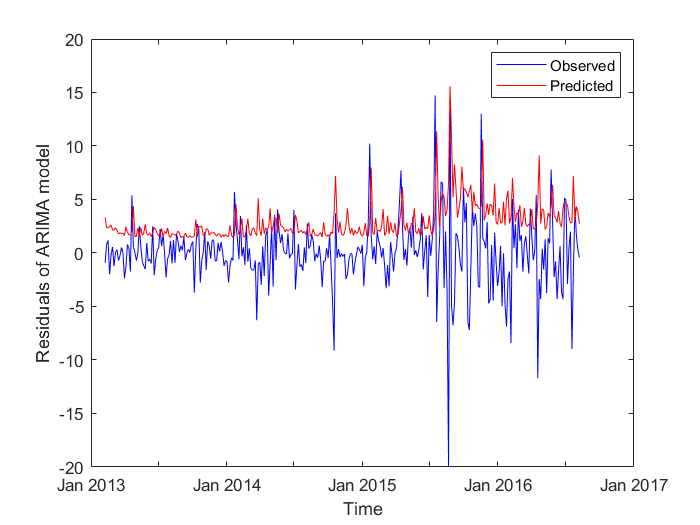

condVar = infer(gEstmdl, res);
condVol = sqrt(condVar);

plot(Train.Time, res, 'b')
hold on
plot(Train.Time, condVol, 'r')
hold off
xlabel('Time')
ylabel('Residuals of ARIMA model')
legend('Observed', 'Predicted')

#### *Standardized residual analysis*

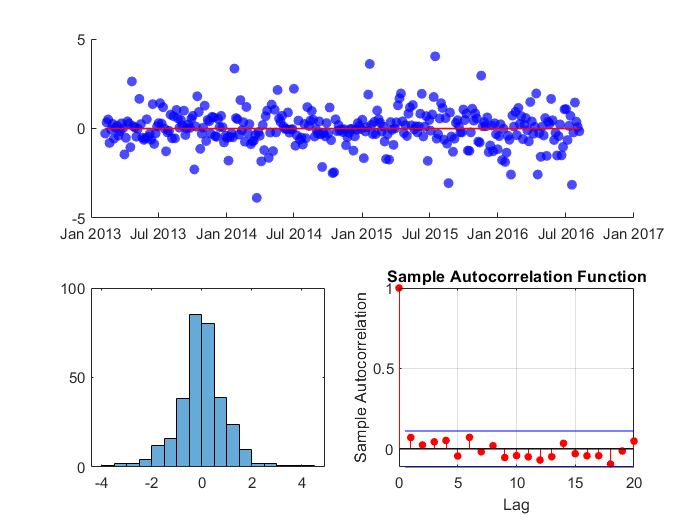

stdres = res ./ condVol;
subplot(2,2, [1 2])
scatter(Train.Time, stdres, 'filled', 'b', 'MarkerFaceAlpha', 0.7)
hold on
plot(Train.Time, 0*Train.close, 'red', 'LineWidth', 1)
hold off
subplot(2,2,3)
histogram(stdres)
subplot(2,2,4)
autocorr(stdres)

**From the above 3 plots we can see that**

- **Standardized residuals have mean approx. 0.**

- **The residuals are normally distributed**

- **The residuals have no significant correlation among each other**

**This justifies our GARCH model.**

## Forecasting

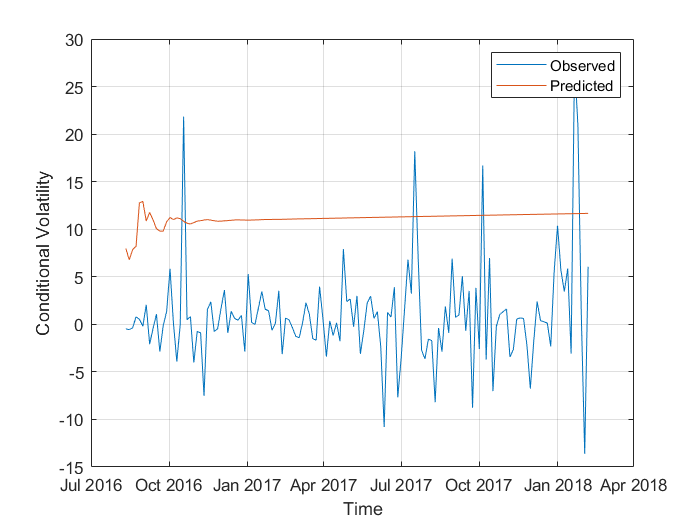

gres = infer(Estmdl, Test.close);
f = forecast(gEstmdl, 137, gres);

figure
plot(Test.Time, gres)
hold on
plot(Test.Time, sqrt(f))
hold off
ylabel('Conditional Volatility')
xlabel('Time')
grid on
legend('Observed', 'Predicted')

## Conclusion

        The GARCH model is able to analyse the volatility of the stock prices and predict how volatile the stock market is.  